# FINGERPRINT RECOGNITION

## READ IN IMAGE

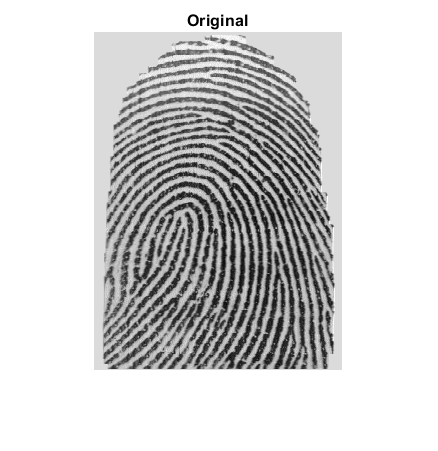

I = imread("1_8.png");

figure, imshow(I,[]); title('Original');

## 1. FILTER

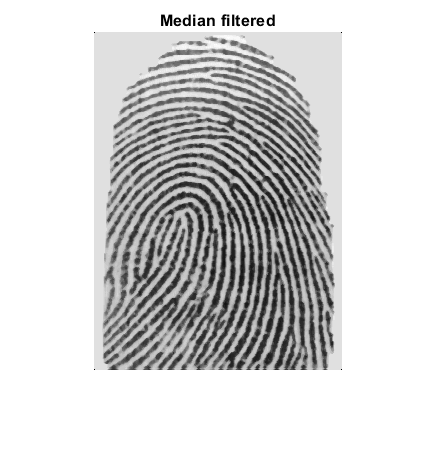

I = medfilt2(I, [3 3]);
I = double(I);
figure; imshow(I, []); title("Median filtered")

## 2. IMAGE NORMALISATION

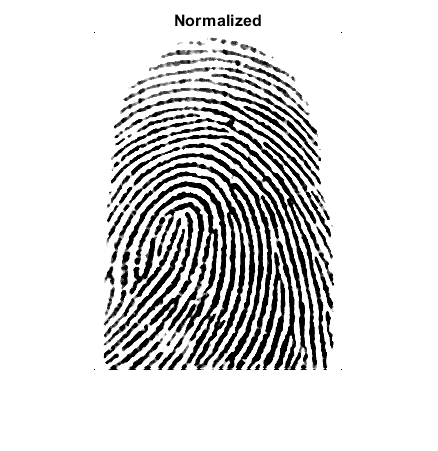

% new mean and variance
M0 = 1;
V0 = 1;
norm_I = normalize(I, M0, V0);
figure, imshow(norm_I); title('Normalized');

## 2. IMAGE SEGMENTATION

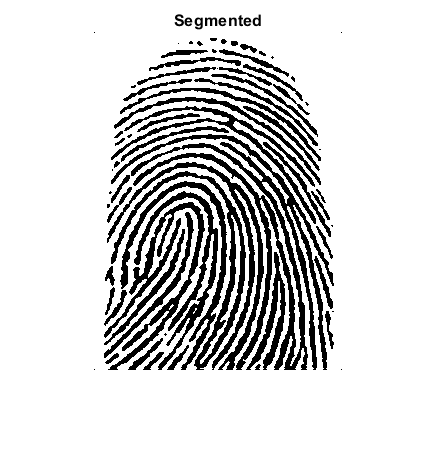

level = multithresh(norm_I);
seg_I = imquantize(norm_I, level);
figure, imshow(seg_I, []); title('Segmented');

## 3. BINARIZED AND THINNED

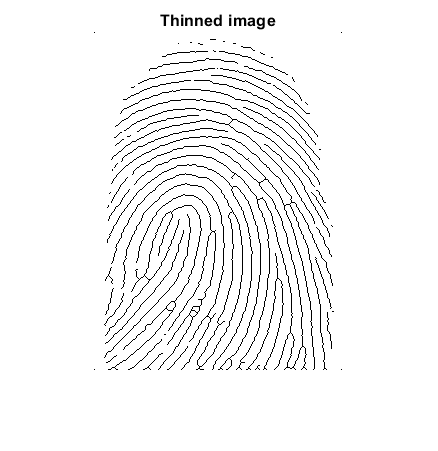

thinned =bin_and_thin(seg_I);
figure; imshow(thinned,[]); title("Thinned image");

## 4. EXTRACTION

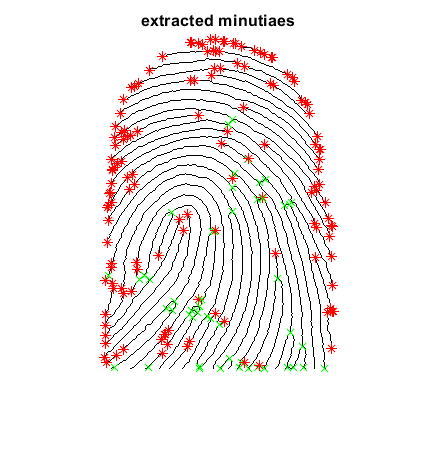

minutiaes = extract_minutiae(thinned);
figure; imshow(~minutiaes,[]); title("extracted minutiaes");hold on;

% Green 'x' are bifurcations
% Red '*' are ridge endings

[y,x] = size(minutiaes);
for j=1: x
    for i=1: y
        if (minutiaes(i,j) == 1)
            plot(j,i , '*r');
        elseif (minutiaes(i,j) == 3)
            plot(j,i, 'xg');
        end
    end
end


[coordinates, type] = coordinate_type_extraction(minutiaes);

## 5. MATCHING

[score, matching_img] = match(coordinates, type);
disp(['Best similarity score: ', num2str(score)]);

Best similarity score: 0.83465


disp(['Closest Matching Image: ' , matching_img]);

Closest Matching Image: 1_2.png
